%% dilution_set_points.m
%
% Author:   Lincoln Scheer
% Date:     1 April 2024
%
% This script file is for calculating MFC set points to dilute two known
% gasses delivered at discrete set points.

clc, clear, close all

Dilution Assumptions

% Dilution Assumptions

ct_low_ppm = 1000;   % Target Low [ppm]
ct_high_ppm = 400;  % Target High [ppm]
resolution = 10;   % No. Dilution Tests
ca_ppm = 3003;       % Tank A Concentration [ppm]
cb_ppm = 0;       % Tank B Concentration [ppm]
qa_lpm = 0.05;       % MFC Tank A [lpm]
qb_lpm = 0.2;       % MFC Tank B [lpm]

% Environment Assumptions
P = 79082.866;            % Atmospheric Pressure [Pa]
T = 293.15;            % Atmostpheric Temp. [K]

% Unit Conversion Anonymous Functions

ppm_to_mol = @(ppm) (ppm*P)/(1e6*8.314*T);
mol_to_ppm = @(mol) (1e6*8.314*mol*T)/P;
lpm_to_cms = @(lpm) lpm/60000;
cms_to_lpm = @(cms) cms*60000;

% Convert To SI Units

% ppm --> mol/m^3
ct_low = ppm_to_mol(ct_low_ppm);
ct_high = ppm_to_mol(ct_high_ppm);
ca = ppm_to_mol(ca_ppm);
cb = ppm_to_mol(cb_ppm);

% slpm -->lpm --> cms
qa = lpm_to_cms(1.0303.*qa_lpm-0.002);
qb = lpm_to_cms(1.2014.*qb_lpm+0.005);

% Governing Equation

ct_eqn = @(ca, cb, qa, qb) (qa.*ca+qb.*cb)./(qa+qb);

% Preprocessing

ct_rng = linspace(ct_low, ct_high, resolution);

qa_min = qa*0.1;
qa_max = qa-qa*0.1;

qb_min = qb*0.1;
qb_max = qb-qb*0.1;

qa_rng = linspace(qa_min, qa_max, resolution);
qb_rng = linspace(qb_min, qb_max, resolution);

[qa_mesh, qb_mesh] = meshgrid(qa_rng, qb_rng);
% manually apply set-points from 6/6 of 3003ppm with 50ccm, and 0ppm with
% 200ccm.
ct_calc = ct_eqn(ca, cb, qa_mesh, qb_mesh);

qa_mesh_lpm = cms_to_lpm(qa_mesh);
qb_mesh_lpm = cms_to_lpm(qb_mesh);
ct_calc_ppm = mol_to_ppm(ct_calc);

target_ct_rng = logspace(log10(ct_low_ppm),log10(ct_high_ppm), resolution);
target_qa_rng = zeros(1,resolution);
target_qb_rng = zeros(1,resolution);
target_ct_rng_calc = zeros(1,resolution);
for i = 1:resolution

    diff = abs(ct_calc_ppm - target_ct_rng(i));

    [row, col, val] = find(diff <= min(min(diff)));
    row = row(1);
    col = col(1);
    tgt = ct_calc_ppm(row, col);
    
    target_ct_rng_calc(i) = tgt(1);
    target_qa_rng(i) = qa_mesh_lpm(row, col);
    target_qb_rng(i) = qb_mesh_lpm(row, col);

end



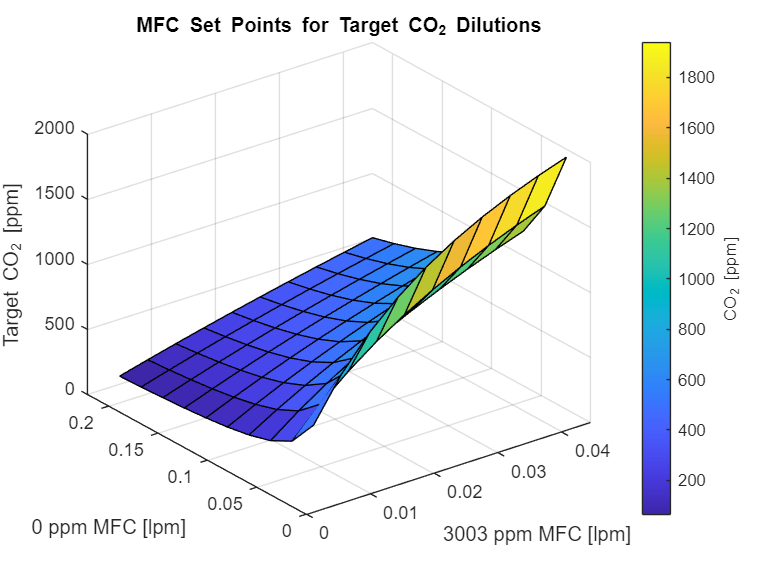

% Surface Plots

surf(qa_mesh_lpm, qb_mesh_lpm, ct_calc_ppm);
a = colorbar;
a.Label.String = 'CO_2 [ppm]';

xlabel("" + ca_ppm + " ppm MFC [lpm]");
ylabel("" + cb_ppm + " ppm MFC [lpm]");
zlabel('Target CO_2 [ppm]');
title("MFC Set Points for Target CO_2 Dilutions");

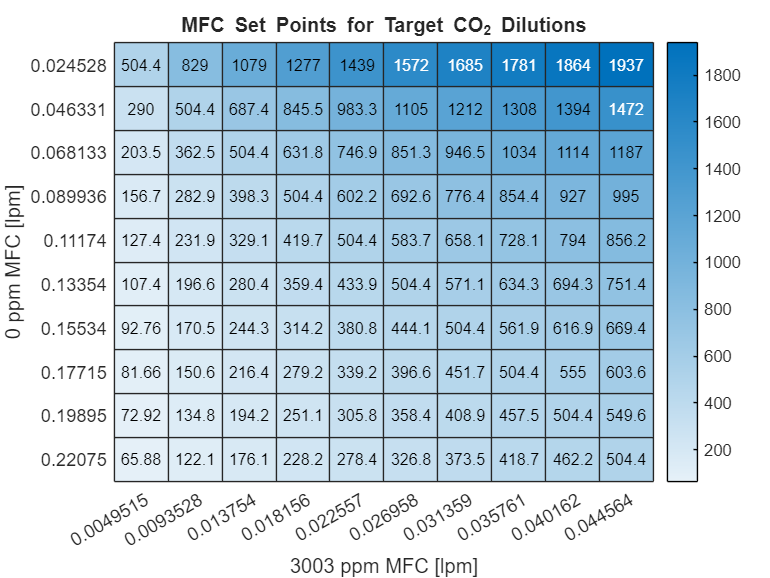

% Heatmap Plots

heatmap(cms_to_lpm(qa_rng), cms_to_lpm(qb_rng), ct_calc_ppm);
title("MFC Set Points for Target CO_2 Dilutions");
xlabel("" + ca_ppm + " ppm MFC [lpm]");
ylabel("" + cb_ppm + " ppm MFC [lpm]");

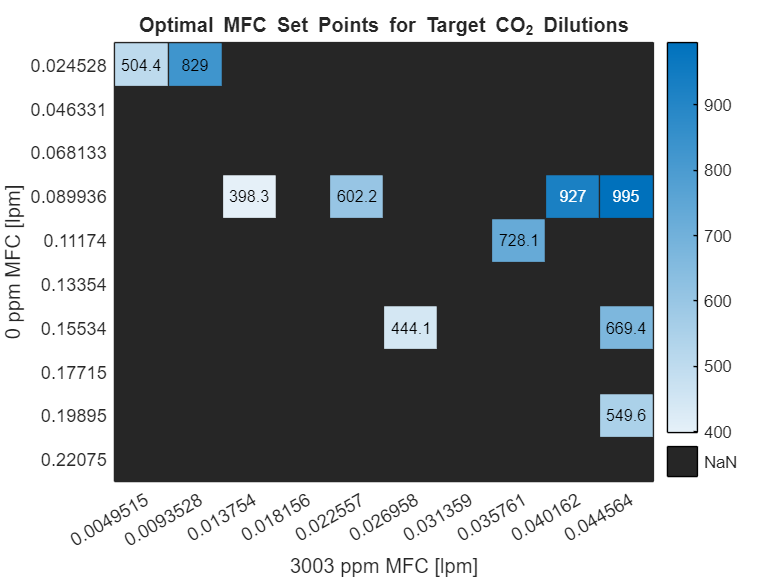


ct_calc_ppm_masked = ct_calc_ppm;
ct_calc_ppm_masked(~ismember(ct_calc_ppm, target_ct_rng_calc)) = NaN;

heatmap(cms_to_lpm(qa_rng), cms_to_lpm(qb_rng), ct_calc_ppm_masked);
title("Optimal MFC Set Points for Target CO_2 Dilutions");
xlabel("" + ca_ppm + " ppm MFC [lpm]");
ylabel("" + cb_ppm + " ppm MFC [lpm]");

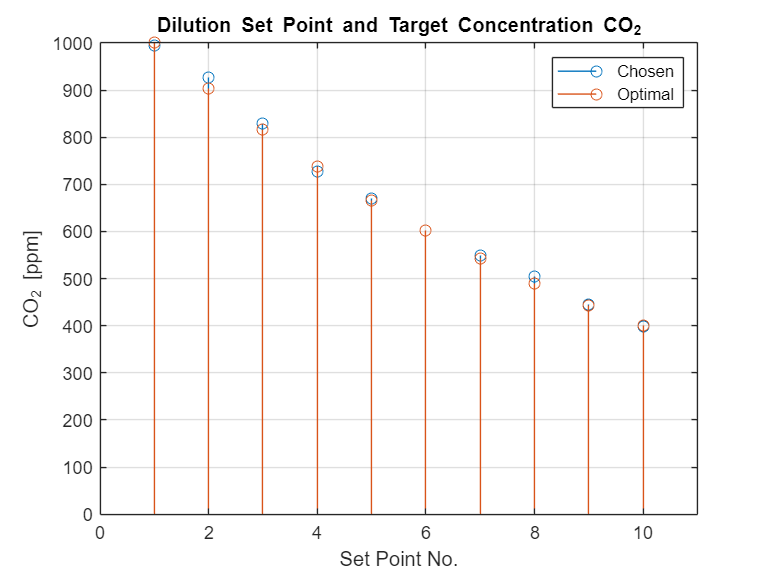


stem(1:resolution, target_ct_rng_calc)
hold on
stem(1:resolution, target_ct_rng)
legend(["Chosen", "Optimal"])
xlabel("Set Point No.");
ylabel("CO_2 [ppm]");
title("Dilution Set Point and Target Concentration CO_2");
grid on
xlim([0, resolution+1])

labels = ["Target CO2 [ppm]", "MFC Set Point w/ " + ca_ppm + " ppm CO2 [lpm]", "MFC Set Point w/ " + cb_ppm + " ppm CO2 [lpm]", "MFC Set Point w/ " + ca_ppm + " ppm CO2 [slpm]", "MFC Set Point w/ " + cb_ppm + " ppm CO2 [slpm]"];
dilution_results = array2table([target_ct_rng_calc', target_qa_rng', target_qb_rng', (target_qa_rng'+0.002)./1.0303, (target_qb_rng'-0.005)./1.2014], "VariableNames", labels);
[C,ia] = unique(dilution_results(:,"Target CO2 [ppm]"));
B = dilution_results(ia,:)

B = 10×5 table
    Target CO2 [ppm]    MFC Set Point w/ 3003 ppm CO2 [lpm]    MFC Set Point w/ 0 ppm CO2 [lpm]    MFC Set Point w/ 3003 ppm CO2 [slpm]    MFC Set Point w/ 0 ppm CO2 [slpm]
    ________________    ___________________________________    ________________________________    ____________________________________    _________________________________

         398.34                       0.013754                             0.089936                              0.015291                              0.070698             
         444.07                       0.026958                              0.15534                              0.028107                               0.12514             
          504.4                      0.0049515                             0.024528                             0.0067471 

writetable(B, 'set_points.csv')
D = B{:,2} + B{:,3};

min(D)

ans = 0.0295

max(D)

ans = 0.2435